# TEMPOmap 64Gene AF546 spot finding

addpath('Z:/Documents/starmap_colab/Code/matlab/');
addpath('Z:/Documents/starmap_colab/Code/matlab/myfunction/');

run_id = '2022-10-07-AF546-spot-finding'

run_id = '2022-10-06-AF546-spot-finding'

% set input path 
input_path = 'Z:/Data/Processed/2022-09-30-Rena-Cardiomyocyte64Gene/'; 

% get input folder
data_dirs = dir(fullfile(input_path, "output", "2022-10-06-registration", "Position*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);

Ndirs = numel(data_dirs);

output_file = 'Z:\Data\Processed\2022-09-30-Rena-Cardiomyocyte64Gene\output\2022-10-06-AF546-spot-finding\AF546_Position001.mat'

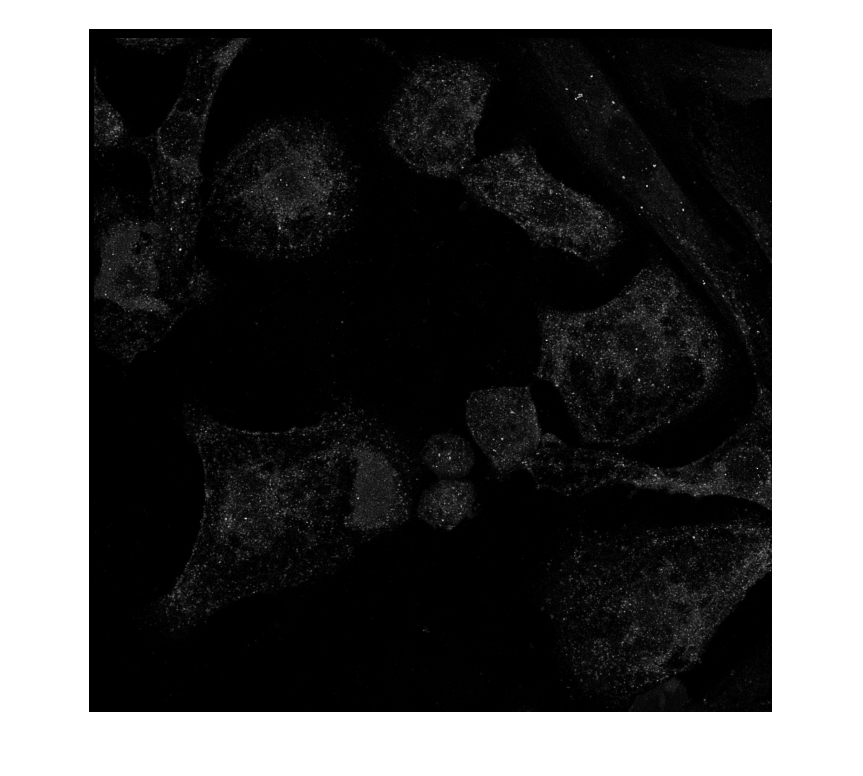

curr_out = 2048×2048×31 logical array
curr_out(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

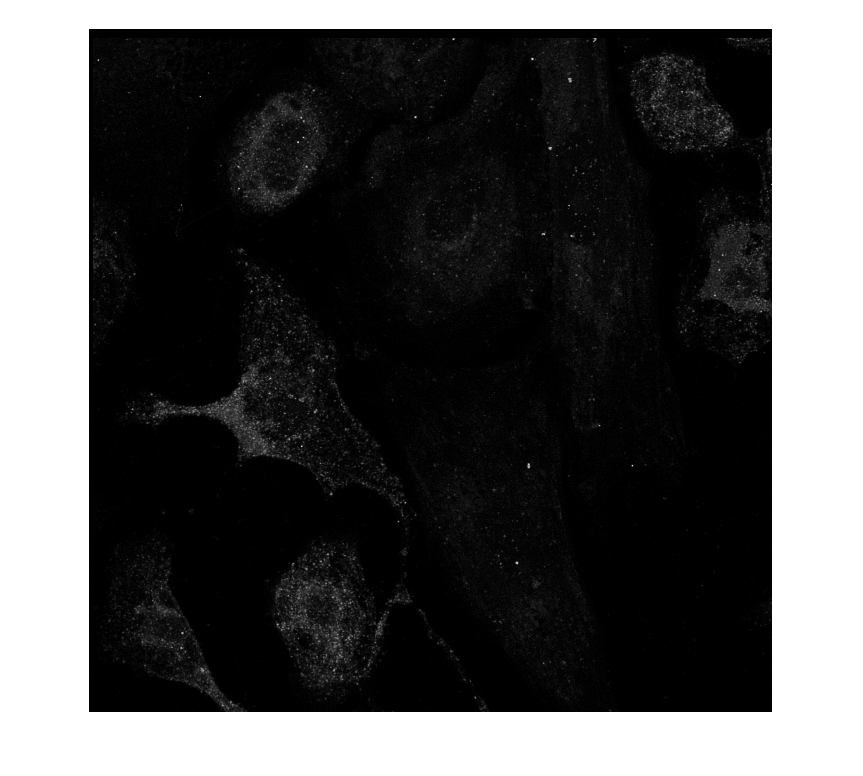

curr_out = 2048×2048×31 logical array
curr_out(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

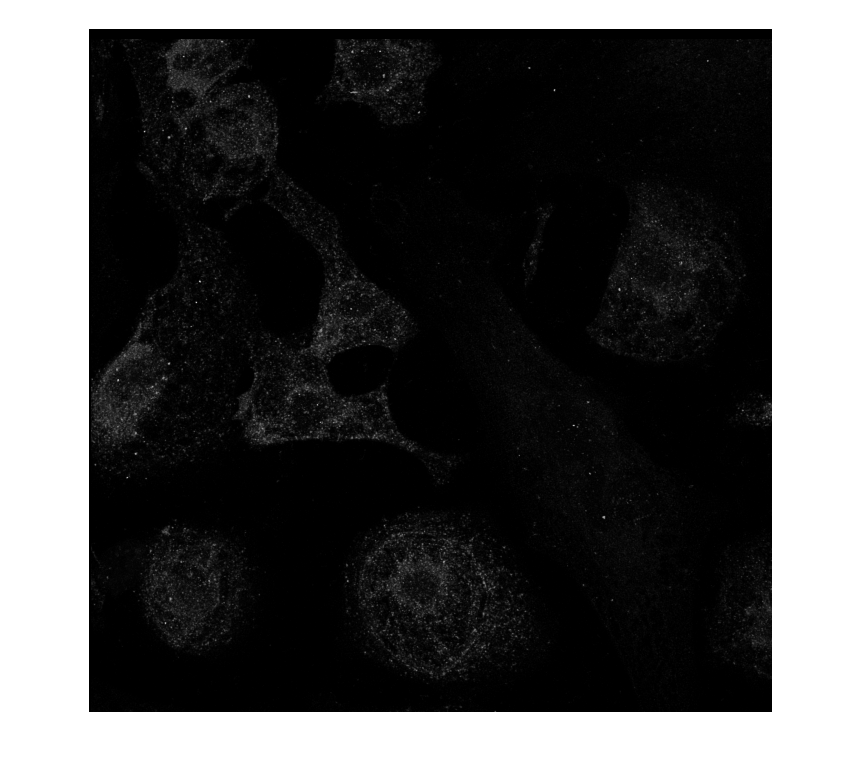

curr_out = 2048×2048×31 logical array
curr_out(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

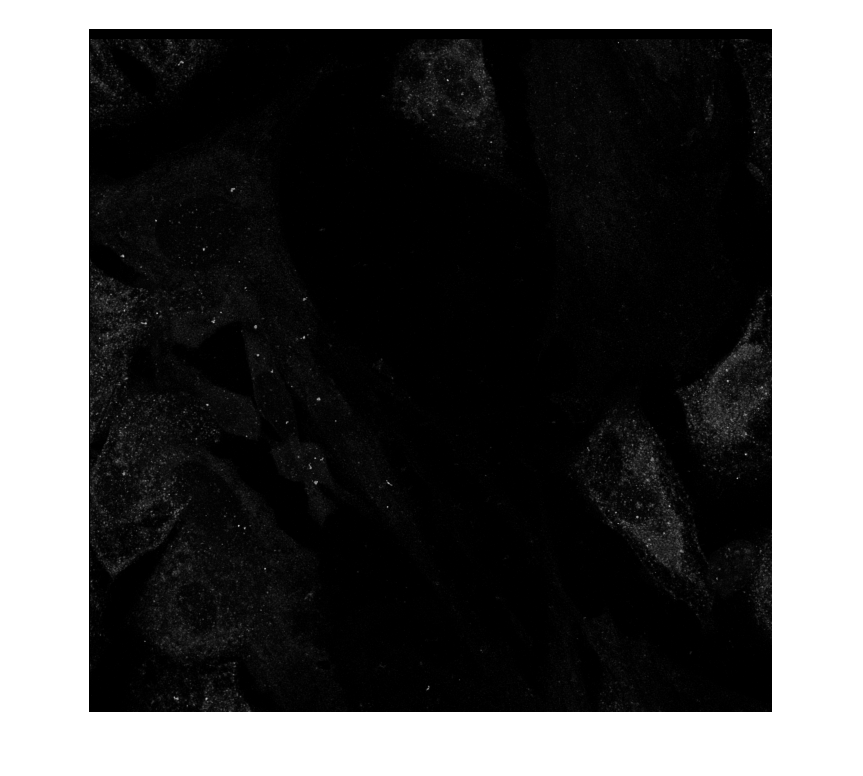

% for p=1:88
for p=1:Ndirs
    current_position = data_dirs{p};
    output_file = fullfile(input_path, 'output', run_id, strcat('AF546_', current_position, '.mat'))

    % read AF546 image
    im_path = dir(fullfile(input_path, "output", "2022-10-06-registration", current_position, "*.tif"));
    im = new_LoadMultipageTiff(fullfile(im_path(1).folder, im_path(1).name), 'uint8', 'uint8', false);
    
    % spot finding
    local_max = imregionalmax(im);
    max_intensity = max(im, [], 'all');
%     curr_out = local_max & im > 0.2 * max_intensity; 
    curr_out = local_max & im > 150
    centroid = regionprops3(curr_out, "Centroid");
    centroid = int16(centroid.Centroid);
    save(output_file, "centroid")

    % save dots image
    im2d = max(im, [], 3);
    plot_centroids(centroid, im2d, 3, 'r')
    saveas(gcf, fullfile(input_path, 'output', run_id, 'dots_image', sprintf("%s.tif", current_position)));
end